## Métodos Numéricos

#### Taller 01: Semana 1

Desarrollemos el ejercicio planteado en el punto 2, con las rutinas disponibles del curso:

% Creación de la función
f = @(x) tan(exp(x)) - (x ./ (x - 2))

f = function_handle with value:
    @(x)tan(exp(x))-(x./(x-2))


% Evaluamos puntos extremos
f([-1.5 0])

ans =    -0.2017    1.5574


% Verifiquemos los argumentos del método
help bisect

  Entrada - f es la funcion introducida con @
 	      - a y b son los extremos izquierdo y derecho
 	      - delta es la tolerancia
  Salida  - c es el cero
 	      - yc = f(c)
  	      - err es el error estimado para  c



% Llamamos el método y verificamos las salidas
[c, ~, error] = bisect(f, -1.5, 0, 1e-6)

c = -1.0845

error = -9.4143e-08

Homologamente revisemos otra forma de crear funciones, *usando la librería simbolica.*

% Limpiamos las variables de la anterior sección
clear

% Definimos f(x): una función f de variable x
syms f(x)

% Definimos la función
f(x) = tan(exp(x)) - x / (x - 2)

$$f(x) = \tan\left({\mathrm{e}}^{x}\right)-\frac{x}{x-2}$$

% Evaluamos los extremos
f([-1.5 0])

$$ans = \left(\begin{array}{cc} \tan\left({\mathrm{e}}^{-\frac{3}{2}}\right)-\frac{3}{7} & \tan\left(1\right) \end{array}\right)$$

% Veamos que salen simbolos, para revisar el valor: Evaluamos
eval(f([-1.5 0]))

ans =    -0.2017    1.5574


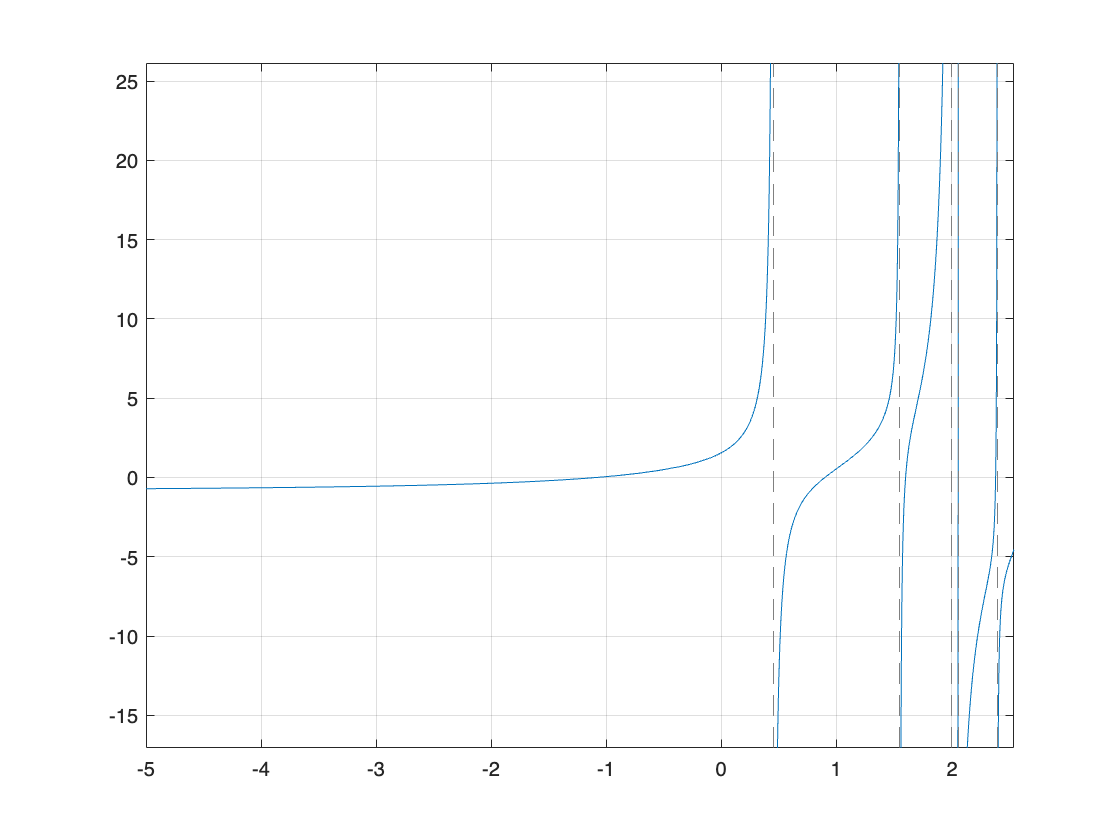

% Gráfiquemos la función
fplot(f)
grid on

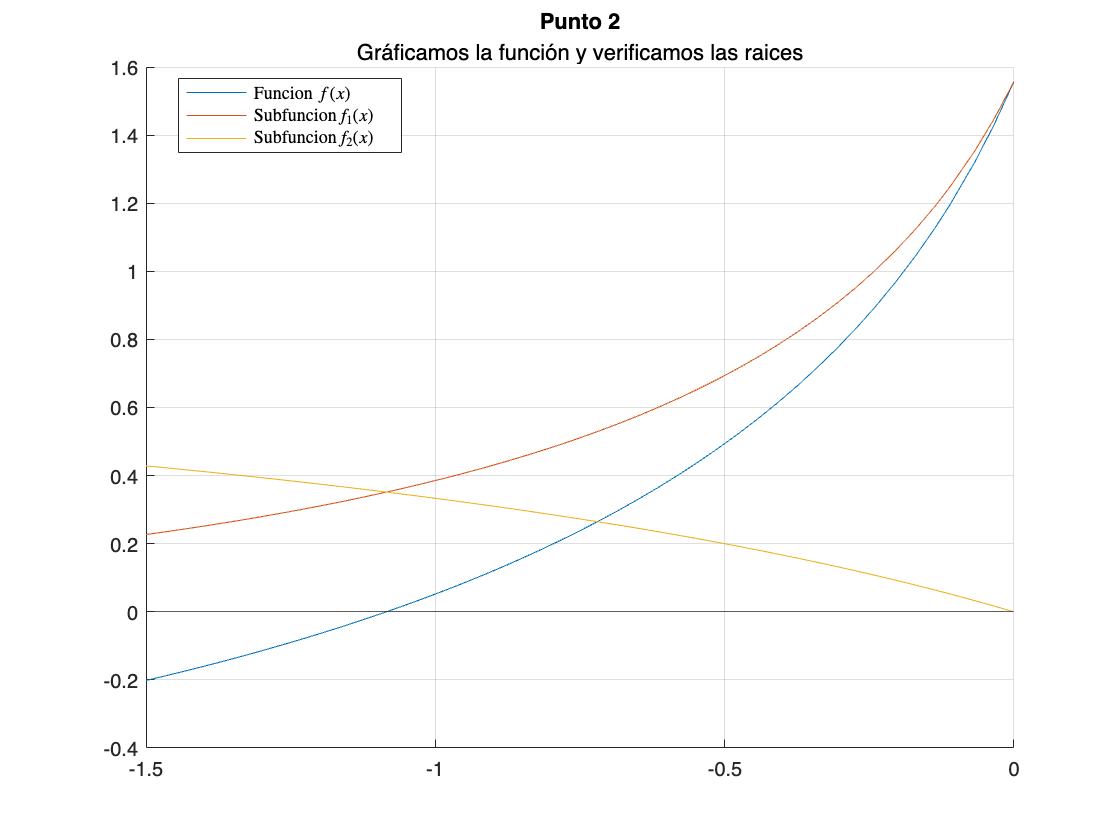

% Cuando le agarramos práctica podemos generar fácilmente material que
% podemos usar y reusar continuamente:
f_1(x) = tan(exp(x));
f_2(x) = x / (x - 2);

clf('reset')
hold on
fplot(f, [-1.5, 0], 'DisplayName', 'Funcion $f(x)$')
fplot(f_1, [-1.5, 0], 'DisplayName', 'Subfuncion $f_1(x)$')
fplot(f_2, [-1.5, 0], 'DisplayName', 'Subfuncion $f_2(x)$')
yline(0, 'HandleVisibility', 'off')
hold off
title('Punto 2')
subtitle('Gráficamos la función y verificamos las raices')
legend('Interpreter', 'latex', 'Location', 'best')
grid on